### Driving towards april tag behaviors

clear all


% Connect to raspi
%     robotPi = raspi('192.168.34.15', 'pi', 'raspberry');
    robotPi = raspi('192.168.33.177', 'pi', 'raspberry');

    roverServos = I2C_Servo_pHAT(robotPi);

% Create connection to the V2 Pi Camera
    robotCam = cameraboard(robotPi, 'Resolution', '1280x720');   
    robotCam.ExposureMode = 'night';
    robotCam.AWBMode = 'fluorescent';
    
    

    img = snapshotCustom(robotCam);
    img = rgb2gray(img);
    cropped_img = img(150:end,:);
    edge_img = edge(cropped_img,"Canny",.06);
    
    imshow(cropped_img)

    bw_image = bwareaopen(edge_img, 10);
        
    [H,T,R] = hough(bw_image);
%     imshow(H,[],'XData',T,'YData',R,...
%                 'InitialMagnification','fit');
%     xlabel('\theta'), ylabel('\rho');
    axis on, axis normal, hold on;
    
    P  = houghpeaks(H,5,'threshold',ceil(0.3*max(H(:))));
    x = T(P(:,2)); y = R(P(:,1));
%     plot(x,y,'s','color','white');
    
    lines = houghlines(bw_image,T,R,P,'FillGap',5,'MinLength',7);
    figure, imshow(cropped_img), hold on
%     figure(figureLineDetection);                            
%     imshow()
    max_len = 0;
    threshold_length = 15;
    for k = 1:length(lines)
       xy = [lines(k).point1; lines(k).point2];   
       % Determine the endpoints of the longest line segment
       len = norm(lines(k).point1 - lines(k).point2);
       slope(k) = 0;
       if ( len > threshold_length)
%            Plot beginnings and ends of lines
           plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green'); 
           plot(xy(1,1),xy(1,2),'x','LineWidth',2,'Color','yellow');
           plot(xy(2,1),xy(2,2),'x','LineWidth',2,'Color','red');
           slope(k) = (xy(2,2) - xy(1,2))/(xy(1,1) - xy(2,1));
       end     
    end
    
    slope_final = mean(slope)
    % 0.02 for neutral
    % 0.03 for positive
    %0.0042 for negative

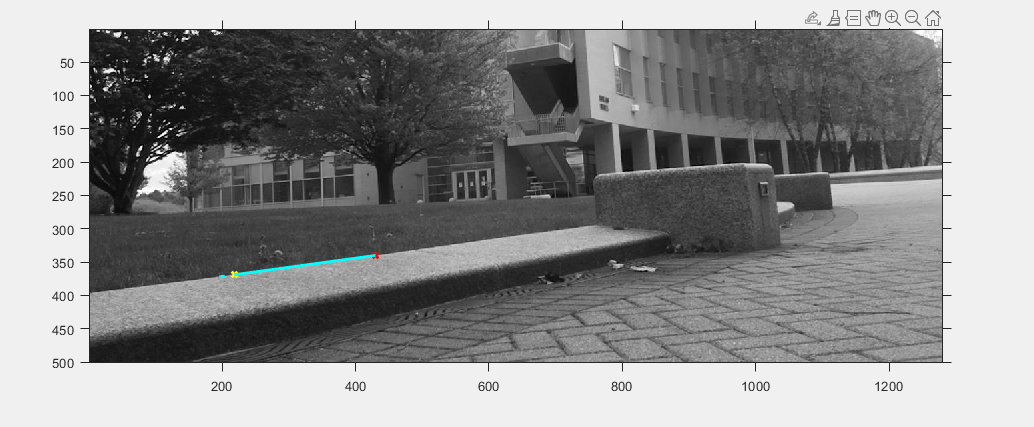

slope = 0.0024

max_slope = 0.1368

    figureLineDetection = figure('name', 'figureLineDetection', 'NumberTitle', 'off', 'Visible', 'on');

    [slope, max_slope]= find_slope_lines(robotCam,figureLineDetection)

  while 1
      
    [slope, max_slope]= find_slope_lines(robotCam,figureLineDetection)
    
    slope = max_slope
    % Rover drive speed
    speed = 44;
 
        % Drive towards april tag % negative slope means turn right
        if slope < 0.008 || slope == inf
            % Steer to right
            disp("steering right")
            bearing = 8;  %degrees
            DriveRover(robotPi,roverServos,bearing, speed);

        else
            % Steer to left % large slope turn left
            disp("steering left")
            bearing = -5;   %degrees
            DriveRover(robotPi,roverServos,bearing, speed);
        end
        pause(4)
        DriveRover(robotPi,roverServos,bearing, 0);
end

DriveRover(robotPi,roverServos,0, 0);

ACT

function pwm = AngleForServo(angle)
pwm = ((angle + 85.21)/1.755) - 2.35;
pwm = pwm(1);
end

function [] = DriveRover(robotPi,roverServos,direction,speed)
    roverServos.setServoPWM(1,AngleForServo(direction));    % commands steering servo
    roverServos.setServoPWM(2,speed);    % commands drive speed controller
end

line detection

function [slope_final, max_slope] = find_slope_lines(robotCam, figureLineDetection)
    img = snapshotCustom(robotCam);
    img = rgb2gray(img);
    cropped_img = img(220:end,:);
    edge_img = edge(cropped_img,"Canny",.06);
    
    threshold_length = 100;

    bw_image = bwareaopen(edge_img, threshold_length);

    imshow(cropped_img)

        
    [H,T,R] = hough(bw_image);
    axis on, axis normal, hold on;
    
    P  = houghpeaks(H,5,'threshold',ceil(0.3*max(H(:))));
%     x = T(P(:,2)); y = R(P(:,1));
%     plot(x,y,'s','color','white');
    
    lines = houghlines(bw_image,T,R,P,'FillGap',5,'MinLength',7);
%     figure, imshow(cropped_img), hold on

    max_len = 0;
    max_slope = 0;
    for k = 1:length(lines)
       xy = [lines(k).point1; lines(k).point2];   
       % Determine the endpoints of the longest line segment
       len = norm(lines(k).point1 - lines(k).point2);
       slope(k) = 0;
       
       if ( len > threshold_length)
%            Plot beginnings and ends of lines
           plot(xy(:,1),xy(:,2),'LineWidth',2,'Color','green'); 
           plot(xy(1,1),xy(1,2),'x','LineWidth',2,'Color','yellow');
           plot(xy(2,1),xy(2,2),'x','LineWidth',2,'Color','red');
           slope(k) = (xy(2,2) - xy(1,2))/(xy(1,1) - xy(2,1));
       end  
       
       if ( len > max_len)
          max_len = len;
          xy_long = xy;
          max_slope = (xy(2,2) - xy(1,2))/(xy(1,1) - xy(2,1));
       end
       
       plot(xy_long(:,1),xy_long(:,2),'LineWidth',2,'Color','cyan');

       figure(figureLineDetection);                            
%        imshow(cropped_img)
       
    end
    
    slope_final = mean(slope);
end